# グループ解析（全参加者の平均）

## 各参加者毎に各task，各条件で平均を求める。

個人の平均波形では，standardまたはdeviantの波形をそれぞれ描くとき，trgを使ってepochを選択していたが，全参加者の平均を求めるときは，trgを使うのは不便（混乱）。この後過去のデータを読み込んで処理するので，データ容量も大きくなり，普通のPCのmatlabで処理できなくなります。

ですので， epochの3次元目を1000から，2に変更します，[１ -> std , 2 -> dev]

data    →　(chl, time, epoch,       freq,prt); (31, 800,1000, 3, 4);

---->>>>

data_ave →　(chl, time, [std or dev],freq,par); (31, 800,   2, 3, 4);


% データが置いてあるpath
folder = '/Users/nyanziba/school/脳計測科学/MATLAB_EEG/Dataset/2016Autumn_mmn_set'

folder = '/Users/nyanziba/school/脳計測科学/MATLAB_EEG/Dataset/2016Autumn_mmn_set'

% current directoryのファイル名を取得
files = dir(fullfile(folder,'*.mat'));
% 複数の .mat ファイル名を取得
names = {files.name}; % 名前の文字列をcell配列型にまとめる
%lamda関数  sと言う引数をもち、1~8文字目まで出力。スライスを出力。
prefixes = cellfun(@(s) s(1:8), names, 'UniformOutput', false);
fn0 = unique(prefixes);
%データの配列を生成。data0にstdとdevを加えたもの。trgの値と整合が取れるようにstd1でdev2
data_ave=zeros(31,800,2,3,size(fn0,2)); % (ch, time, [std or dev],[1010 or 1030 , 1050],par)

% for chl=1:31
    for par=1:size(fn0,2)
        data_ave(:,:,1,1,par)=mean(data(:,:,trg(:,1,par)==1,1,par),3,'omitnan'); % 1010Hz % standard
        data_ave(:,:,2,1,par)=mean(data(:,:,trg(:,1,par)==2,1,par),3,'omitnan'); % 1010Hz % deviant
        data_ave(:,:,1,2,par)=mean(data(:,:,trg(:,2,par)==1,2,par),3,'omitnan'); % 1030Hz % standard
        data_ave(:,:,2,2,par)=mean(data(:,:,trg(:,2,par)==2,2,par),3,'omitnan'); % 1030Hz % deviant
        data_ave(:,:,1,3,par)=mean(data(:,:,trg(:,3,par)==1,3,par),3,'omitnan'); % 1050Hz % standard
        data_ave(:,:,2,3,par)=mean(data(:,:,trg(:,3,par)==2,3,par),3,'omitnan'); % 1050Hz % deviant
    end
% end
% 参考
% data->(ch,time,epoch,freq,prt); (31,800,1000,3,2);
% epoch 1 -> standard, 2-> deviant
% freq: 1-> 1010 Hz, 2-> 1030 Hz,  3-> 1050 Hz
% prt: 24112801 -> 1, 24120501 -> 2, 24121201-> 3, 24121202-> 4

% trg -> (epoch,freq,part) %  1 -> standard, 2-> deviant
% epoch -> 1:1000
% freq: 1-> 1010 Hz, 2-> 1030 Hz,  3-> 1050 Hz
% prt: 24112801 -> 1, 24120501 -> 2, 24121201-> 3, 24121202-> 4

## data_aveの保存

年度ごとに名前を変えて保存しておく。

data_ave2016=data_ave;
save('2016data_ave.mat','data_ave2016')

## data_aveにまとめる

data_ave=zeros(31,800,2,3,00); % (ch, time, [std or dev],[1010 or 1030 , 1050],par)

list_year = [2016, 2017, 2018, 2022, 2023, 2024, 2025]

list_year =         2016        2017        2018        2022        2023        2024        2025


data_by_year = struct();
%2016年
% data_ave2016=zeros(31,800,2,3,size(fn0,2));
% % 2017年
% data_ave2017=zeros(31,800,2,3,size(fn0,2));
% % 2018年
% data_ave2018=zeros(31,800,2,3,size(fn0,2));
% % 2022年
% data_ave2022=zeros(31,800,2,3,size(fn0,2));
% % 2023年
% data_ave2023=zeros(31,800,2,3,size(fn0,2));
% % 2024年
% data_ave2024=zeros(31,800,2,3,size(fn0,2));
% % 2025年
% data_ave2025=zeros(31,800,2,3,size(fn0,2));
folder = '/Users/nyanziba/school/脳計測科学/MMN_avg';
startYear = 2016;
endYear   = 2025;

data_by_year = struct();

for y = startYear:endYear
    fname = sprintf('%ddata_ave.mat', y);           % ファイル名を作成
    fpath = fullfile(folder, fname);         % フルパス
    if exist(fpath, 'file')
        load(fpath);                     % ここで読み込む
        data_by_year.(sprintf('y%d', y)) = S;
    else
        warning('File not found: %s', fpath);
    end
end


for y = list_year
    vname = sprintf('data_ave%d', y); % 例: 'data_ave2025'
    if exist(vname, 'var') == 1
        data_by_year.(sprintf('y%d', y)) = evalin('base', vname);
    else
        warning('変数が見つかりません: %s', vname);
    end
end


data_ave = cat(5, data_by_year.y2016, data_ave2017)

data_ave = data_ave(:,:,1,1,1) =

   -0.0414   -0.0249   -0.0116   -0.0021    0.0032    0.0042    0.0007   -0.0067   -0.0178   -0.0319   -0.0482   -0.0660   -0.0842   -0.1020   -0.1184   -0.1327   -0.1441   -0.1522   -0.1565   -0.1570   -0.1536   -0.1466   -0.1363   -0.1235   -0.1087   -0.0928   -0.0767   -0.0613   -0.0474   -0.0358   -0.0272   -0.0222   -0.0212   -0.0243   -0.0316   -0.0429   -0.0577   -0.0755   -0.0954   -0.1168   -0.1386   -0.1598   -0.1796   -0.1969   -0.2110   -0.2213   -0.2270   -0.2281   -0.2243   -0.2158   -0.2028   -0.1858   -0.1655   -0.1428   -0.1184   -0.0934   -0.0687   -0.0453   -0.0239   -0.0054    0.0099    0.0215    0.0293    0.0334    0.0341    0.0319    0.0276    0.0218    0.0156    0.0100    0.0060    0.0047    0.0068    0.0132    0.0244    0.0407    0.0622    0.0887    0.1196    0.1543    0.1917    0.2305    0.2693    0.3066    0.3408    0.3702    0.3934    0.4089    0.4157    0.4127    0.3995    0.3758    0.3417    0.2980    0.2454    0.1854    0.

data_ave = cat(5, data_ave, data_ave2018); % Concatenate 2018 data
data_ave = cat(5, data_ave, data_ave2022); % Concatenate 2022 data
data_ave = cat(5, data_ave, data_ave2023); % Concatenate 2023 data
data_ave = cat(5, data_ave, data_ave2024); % Concatenate 2024 data
data_ave = cat(5, data_ave, data_ave2025); % Concatenate 2025 data


## plot ERP data(grand average)

何も触らなくて良いです。 scriptを理解したらctl＋enterで走らせて下さい。

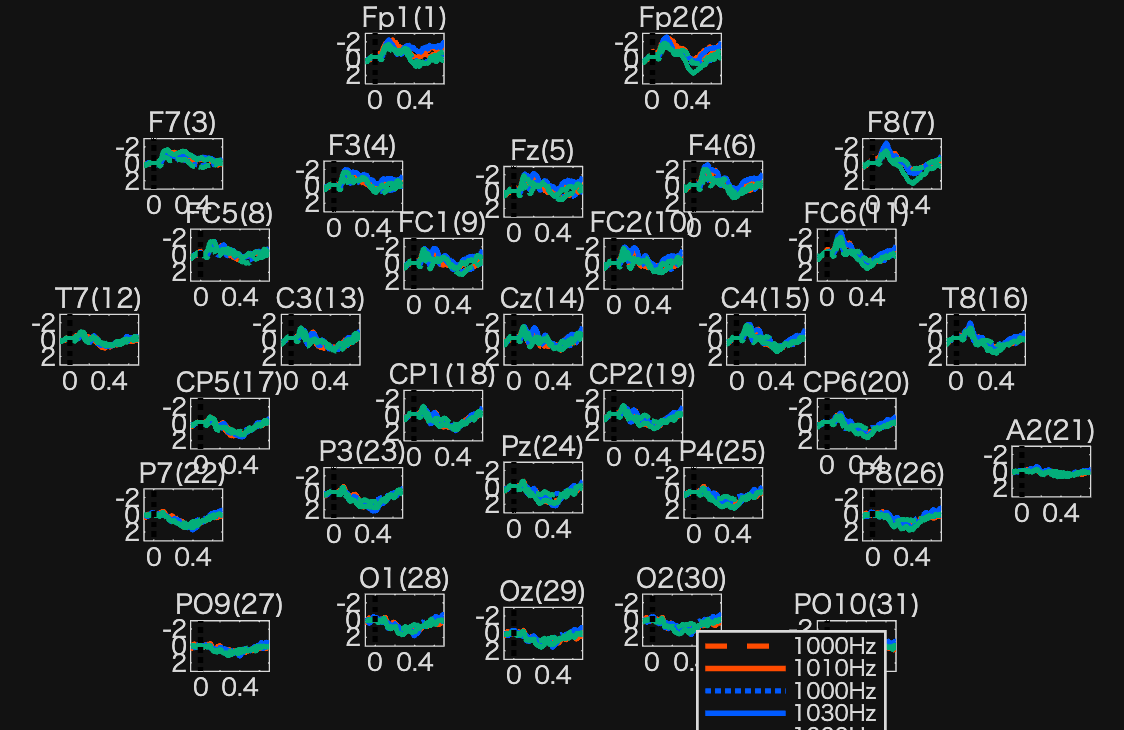

fs = 1000; % サンプリング周波数
N=size(data_ave,2); % データ長 data(ch,time,blk,knd);% 1->1050 Hz, 2->1010 Hz
marker=zeros(2,2);
marker(:,1)=0.0;
marker(1,2)=-20;
marker(2,2)=20;
 
load('EEG_locs_new.mat');

sz = get(0, 'ScreenSize');
figure('Position', [sz(1) sz(2) sz(3) sz(4)])
% figure

x=linspace(-0.1,(N-100)/fs,N);

for chl=1:size(sloc,1)
    subplot('position',[sloc(chl,1) sloc(chl,2) 0.07 0.07])
    hold on
    y1 = mean(data_ave(chl,:,1,1,:),5,'omitnan');
    y2 = mean(data_ave(chl,:,2,1,:),5,'omitnan');
    y3 = mean(data_ave(chl,:,1,2,:),5,'omitnan');
    y4 = mean(data_ave(chl,:,2,2,:),5,'omitnan');
    y5 = mean(data_ave(chl,:,1,3,:),5,'omitnan');
    y6 = mean(data_ave(chl,:,2,3,:),5,'omitnan');

    plot(x,y1,'Color', [255  75   0]/255,'LineWidth',2,'LineStyle','--'); % 1000Hz % standard
    plot(x,y2,'Color', [255  75   0]/255,'LineWidth',2); % 1010Hz % deviant
    plot(x,y3,'Color', [  0  90 255]/255,'LineWidth',2,'LineStyle',':'); % 1000Hz % standard
    plot(x,y4,'Color', [  0  90 255]/255,'LineWidth',2); % 1030Hz % deviant
    plot(x,y5,'Color', [  3 175 122]/255,'LineWidth',2,'LineStyle','-.'); % 1000Hz % standard
    plot(x,y6,'Color', [  3 175 122]/255,'LineWidth',2); % 1050Hz % deviant
    axis('ij')

    ymx=10;
    title([ ch_name{chl} '(' num2str(chl) ')' ]) % titleを付けます。
    xlim([-0.1 0.7])
    ylim([-3 3])
    plot(marker(:,1),marker(:,2),'k:','LineWidth',2);
    set(gca,'box','on');
    set(gca,'linewidth',1)
end
legend('1000Hz', '1010Hz', '1000Hz', '1030Hz', '1000Hz', '1050Hz')
makeSubplotsClickable();

## plot ERP data(grand average差)

deviant から standardを引いた波形を作成してください。

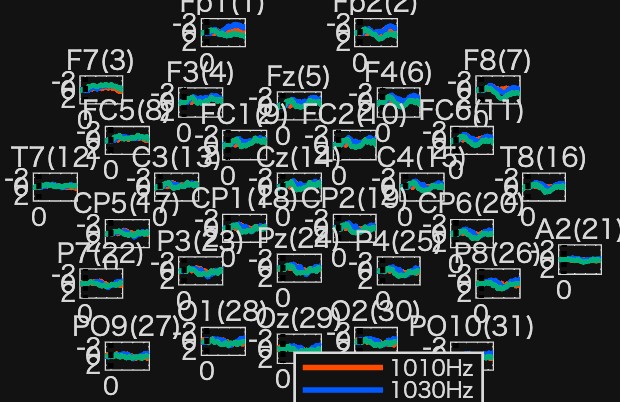


fs = 1000; % サンプリング周波数
N=size(data_ave,2); % データ長 data(ch,time,blk,knd);% 1->1050 Hz, 2->1010 Hz
marker=zeros(2,2);
marker(:,1)=0.0;
marker(1,2)=-20;
marker(2,2)=20;
 
load('EEG_locs_new.mat');

sz = get(0, 'ScreenSize');
figure('Position', [sz(1) sz(2) sz(3) sz(4)])
% figure

x=linspace(-0.1,(N-100)/fs,N);

for chl=1:size(sloc,1)
    subplot('position',[sloc(chl,1) sloc(chl,2) 0.07 0.07])
    hold on
    y1 = mean(data_ave(chl,:,1,1,:),5,'omitnan');
    y2 = mean(data_ave(chl,:,2,1,:),5,'omitnan');
    y3 = mean(data_ave(chl,:,1,2,:),5,'omitnan');
    y4 = mean(data_ave(chl,:,2,2,:),5,'omitnan');
    y5 = mean(data_ave(chl,:,1,3,:),5,'omitnan');
    y6 = mean(data_ave(chl,:,2,3,:),5,'omitnan');

    plot(x,y2-y1,'Color', [255  75   0]/255,'LineWidth',2); % 1010Hz % deviant
    plot(x,y4-y3,'Color', [  0  90 255]/255,'LineWidth',2); % 1030Hz % deviant
    plot(x,y6-y5,'Color', [  3 175 122]/255,'LineWidth',2); % 1050Hz % deviant
    axis('ij')

    ymx=10;
    title([ ch_name{chl} '(' num2str(chl) ')' ]) % titleを付けます。
    xlim([-0.1 0.7])
    ylim([-3 3])
    plot(marker(:,1),marker(:,2),'k:','LineWidth',2);
    set(gca,'box','on');
    set(gca,'linewidth',1)
end
legend( '1010Hz',  '1030Hz', '1050Hz')

makeSubplotsClickable();

makeSubplotsClickable は現在のフォルダーまたは MATLAB パス上に見つかりませんが、次の場所にあります。
 /Users/nyanziba/school/脳計測科学/MATLAB_EEG/practice2025_lecture

MATLAB の現在のフォルダーを変更 または そのフォルダーを MATLAB パスに追加。